# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgm.mlx
    ---------------
    This code solves the stochastic growth model using value function iteration.

%}

## Model: Stochastic Growth Model.

## The Model.

The optimization problem is


$$\underset{\{c_t\}_{t=0}^{T-1},\{a_t\}_{t=1}^{T-1}}{\text{max}}U= \sum_{t=0}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } a_{t+1} = (1+r)(a_t + y_t - c_t) \text{ ,}\end{array} $$



$$\[
y_t =
\begin{cases} 
\bar{y} & \text{if } t < t_r, \\
\kappa \bar{y} & \text{if } t \geq t_r,
\end{cases}
\]$$



$$a_0 \text{ given , }$$



$$a_T = 0,$$



$$c_t > 0\text{ .}$$


## Recursive Formulation.

The recursive formulation is


$$U_t(a_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta U_{t+1}(a_{t+1})$$


 
$$\begin{array}{r l} \text{s.t. } a_{t+1} = (1+r)(a_t + y_t - c_t) \text{ ,}\end{array} $$



$$\[
y_t =
\begin{cases} 
\bar{y} & \text{if } t < t_r, \\
\kappa \bar{y} & \text{if } t \geq t_r,
\end{cases}
\]$$



$$a_0 \text{ given , }$$



$$a_T = 0,$$



$$c_t > 0\text{ .}$$


We have:


$$c_t = -\frac {a_t+1}{1 + r} +a_t+ y_t$$


Substituting the constraint gives


$$V_t(W_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{\left(\frac{-a_{t+1}}{1+r}+a_t + y_t\right)^{1-\sigma}}{1-\sigma} + \beta U_{t+1}(a_{t+1})$$


## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\USER\Documents\GitHub\Problem_Set_2_Dynamic_Macroeconomics\Question 1'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\USER\Documents\GitHub\Problem_Set_2_Dynamic_Macroeconomics\Question 1 



## Set the parameters and generate the state space.

Calls: model.m.

We cannot directly compute the steady state capital as before because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = q_model.setup; % Set parameters.

    Age    MeanLogIncome      Gt  
    ___    _____________    ______

    18        8.9179        7464.2
    19        8.7391        6242.5
    20        9.0004          8106
    21         9.753         17206
    22        9.4334         12499
    23        9.2563         10470
    24        9.7931         17909
    25        9.7885         17827
    26        9.4933         13271
    27        9.5687         14310
    28        9.5448         13972
    29         9.803         18087
    30         9.844         18846
    31        9.7424         17025
    32        9.4747         13027
    33        9.5412         13921
    34        9.6011         14780
    35        9.6213         15082
    36        9.6356         15300
    37        9.4921         13254
    38        9.5728         14369
    39        9.5341         13823
    40        9.4813         13112
    41        9.4115  

par = q_model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: hj_solve.m, and hj_model.m.

As in the deterministic case, we will solve the model using value function iteration using 


$$V(k_t) = \frac{1}{1-\beta} \frac{\left(A_tk_t^{\alpha}-(1-\delta)k_t\right)^{1-\sigma}}{1-\sigma} \ ,$$


as a guess.

t = cputime;
sol = q_solve.cs_q_model_fin(par); % Solve the model using Value Function Iteration.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.3281 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the deterministic growth model. The difference now is that because there are different levels of productivity, there will be a separate function for each level. For example, the seven production functions correspond to different levels of $A_t$. The blue line is production at the lowest level of $A_t$ while the red line is production at the highest level. The general pattern is that the higher $A_t$ is, the more resources there are for consumption, saving, and investment.

Because of productivity fluctuations, there is not a deterministic steady state level. Instead, the variables co-move with the productivity shocks. When productivity is low, output, consumption, and investment are low. Similarly, these variables are high when there are high productivity shocks. Utility in each period fluctuates with consumption.

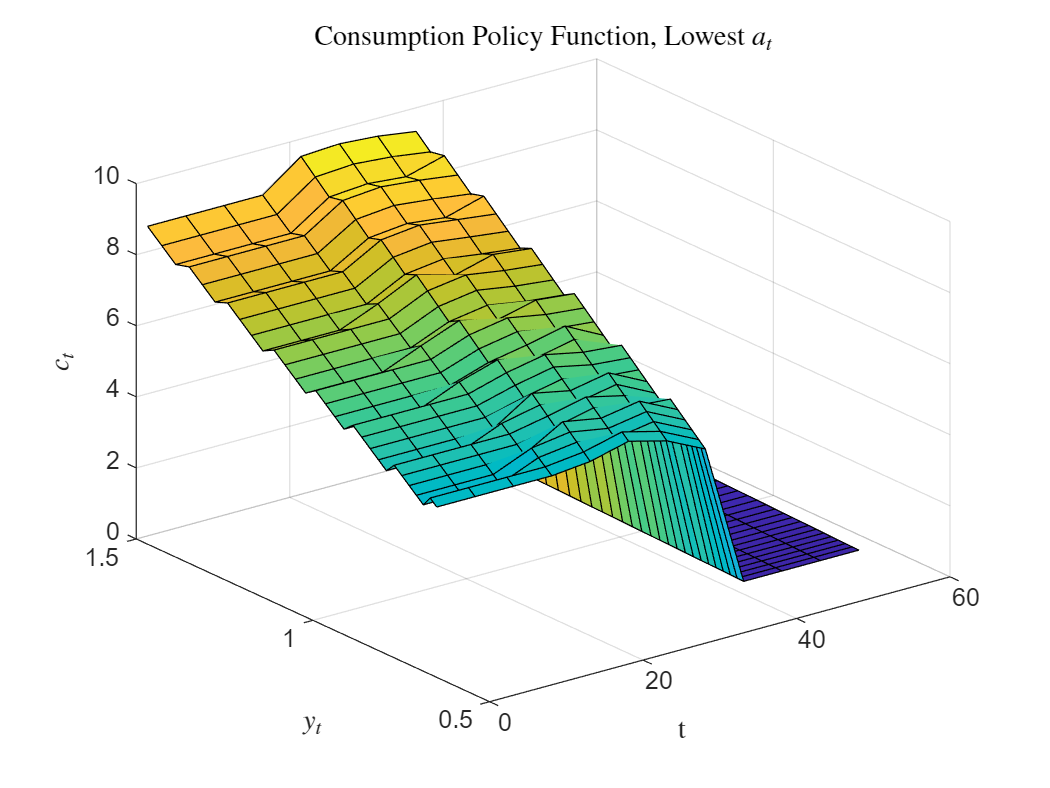

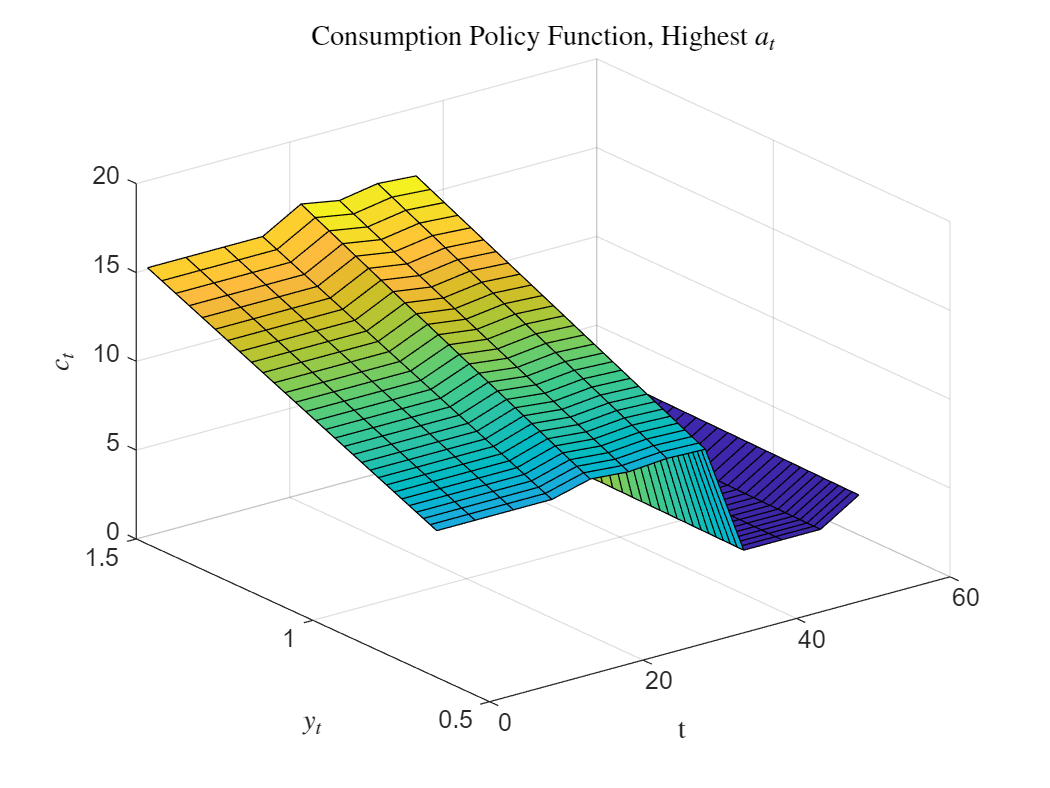

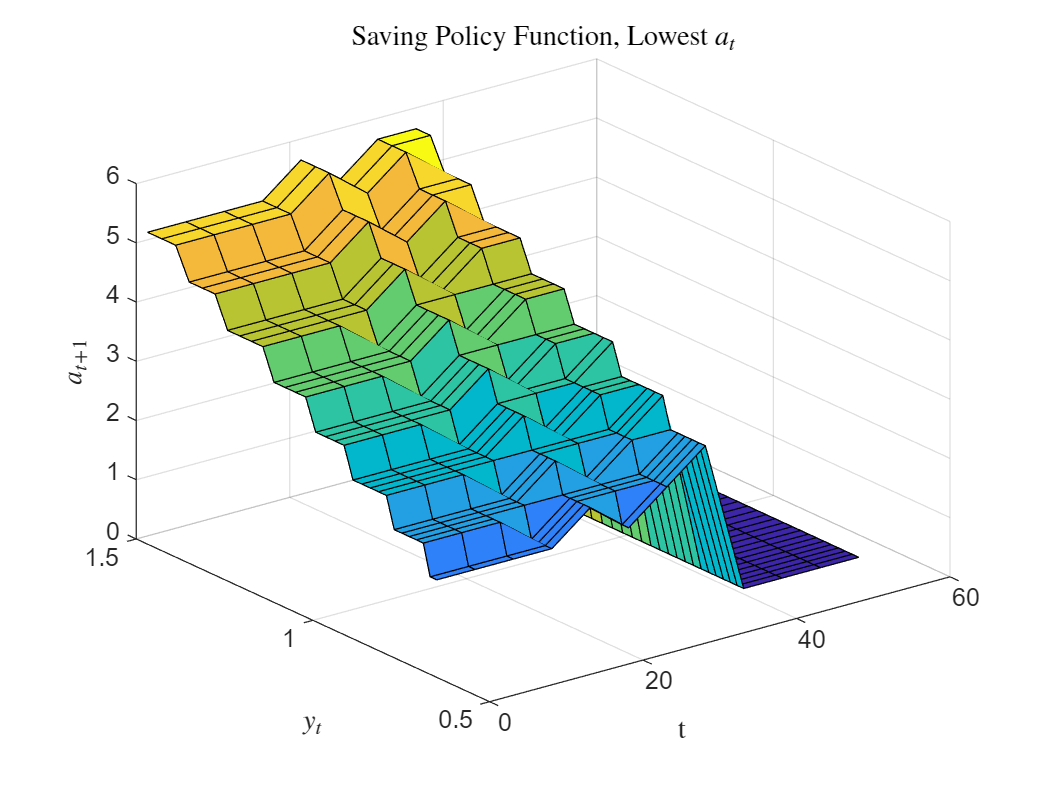

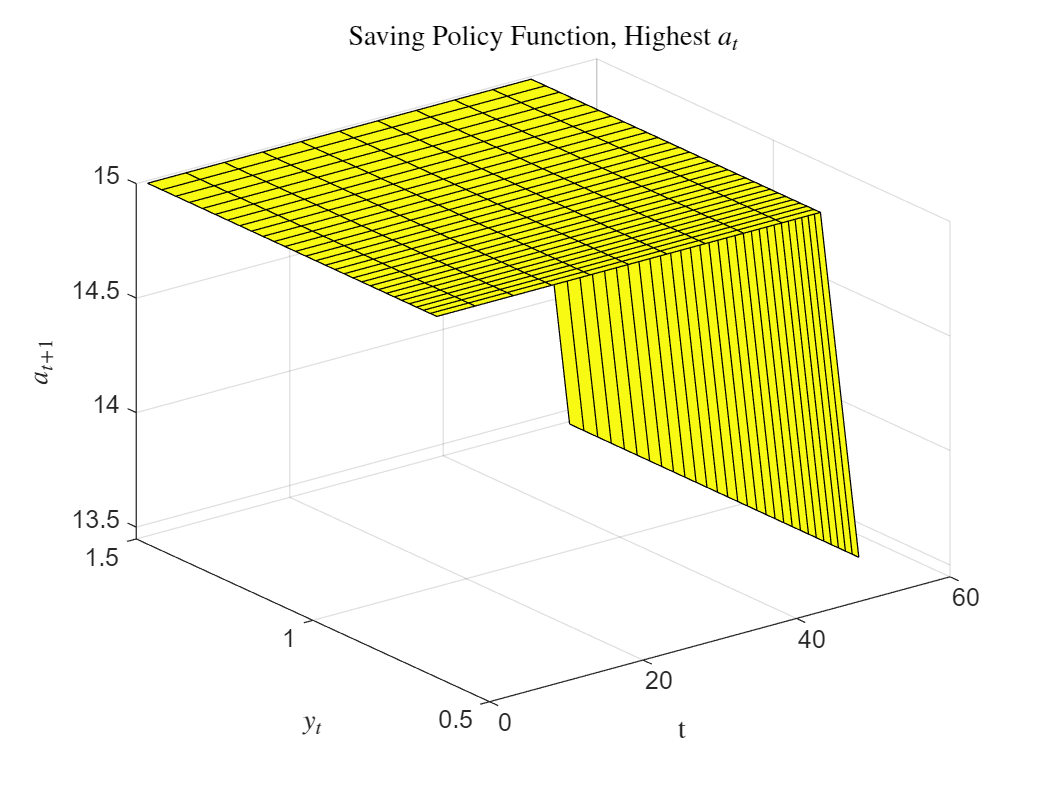

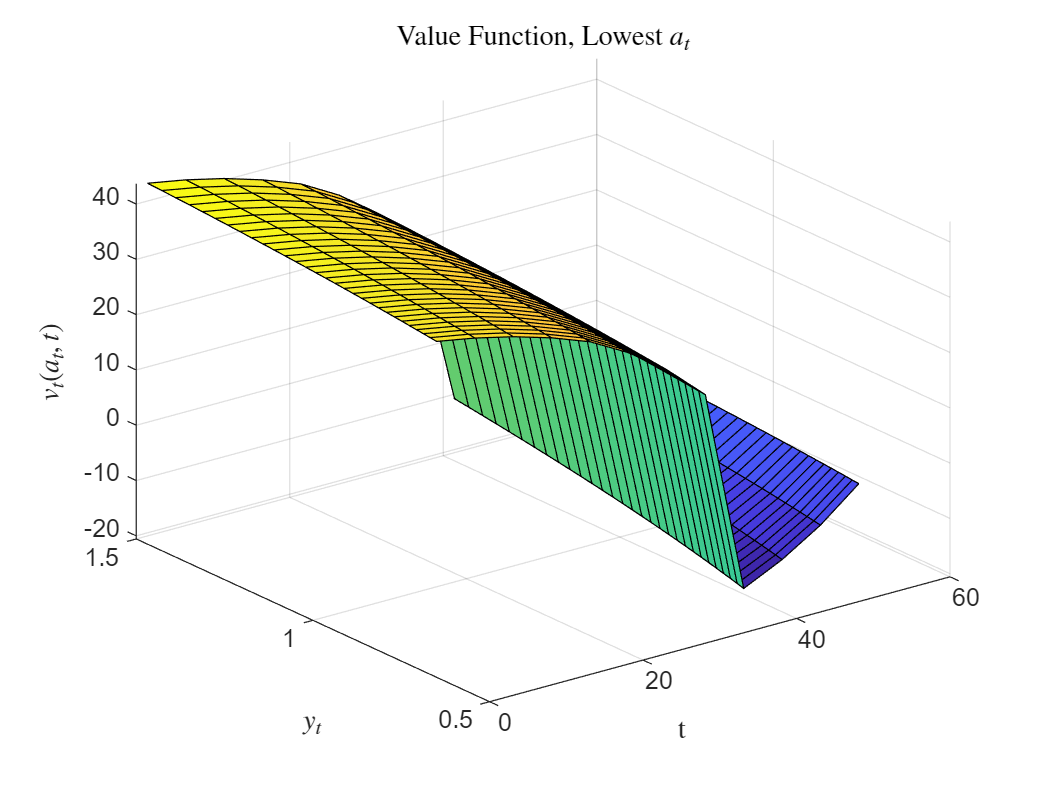

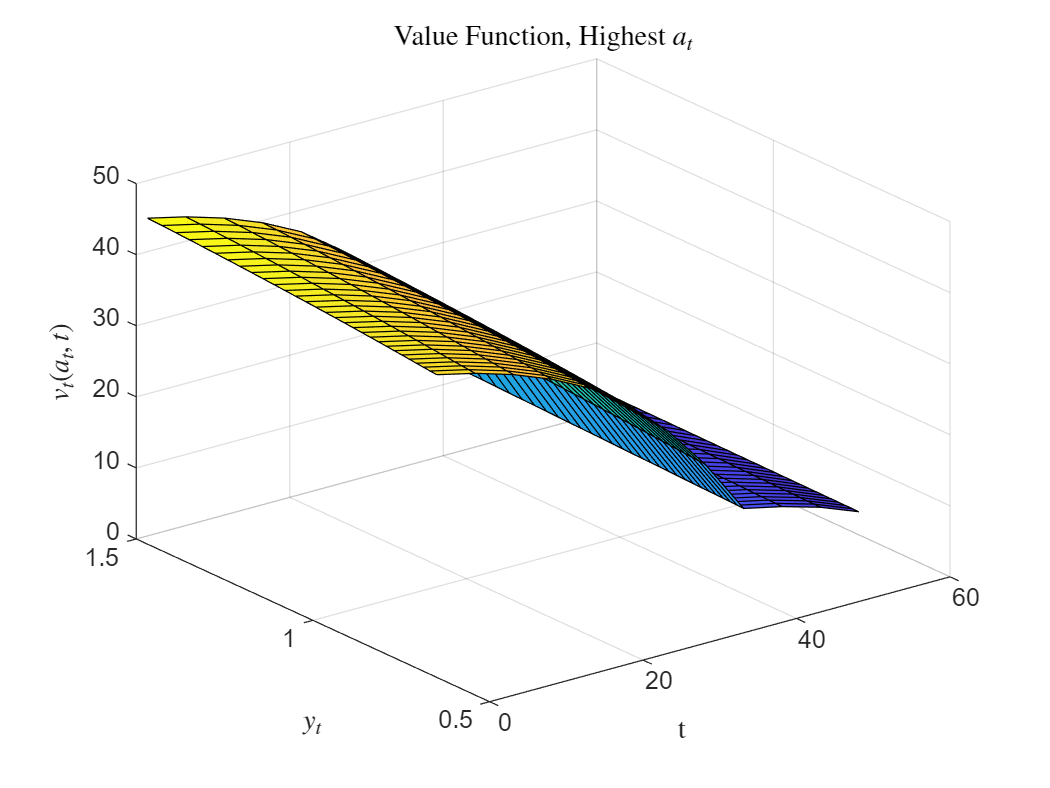

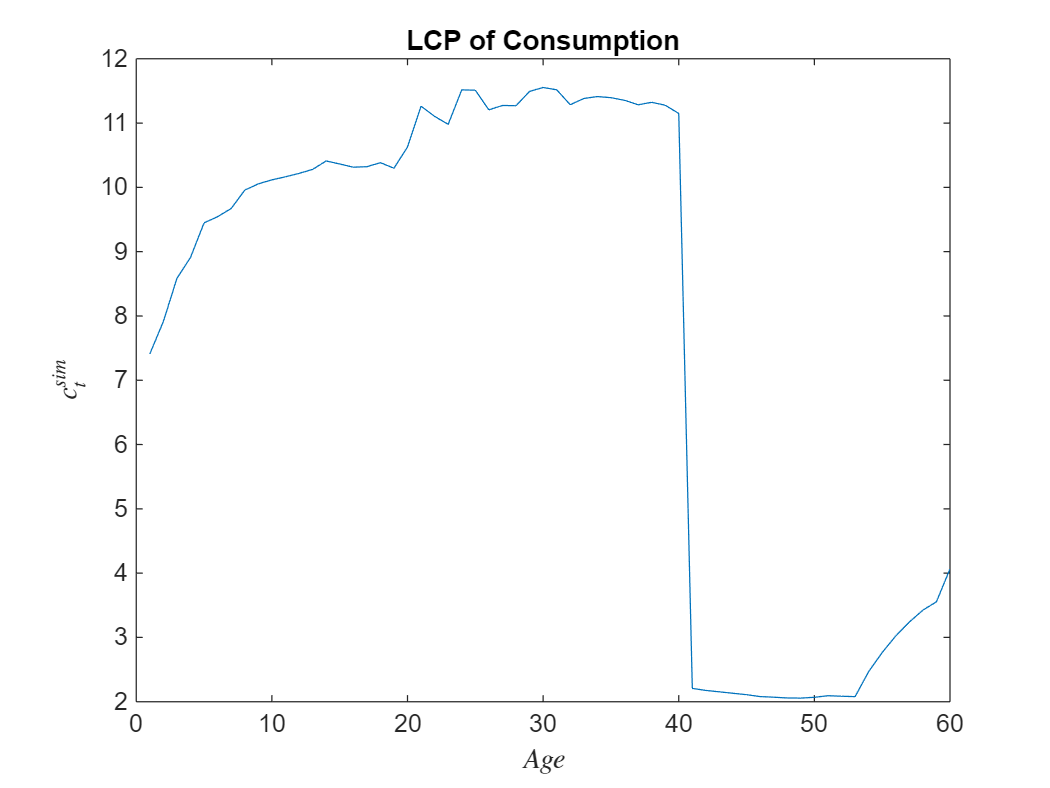

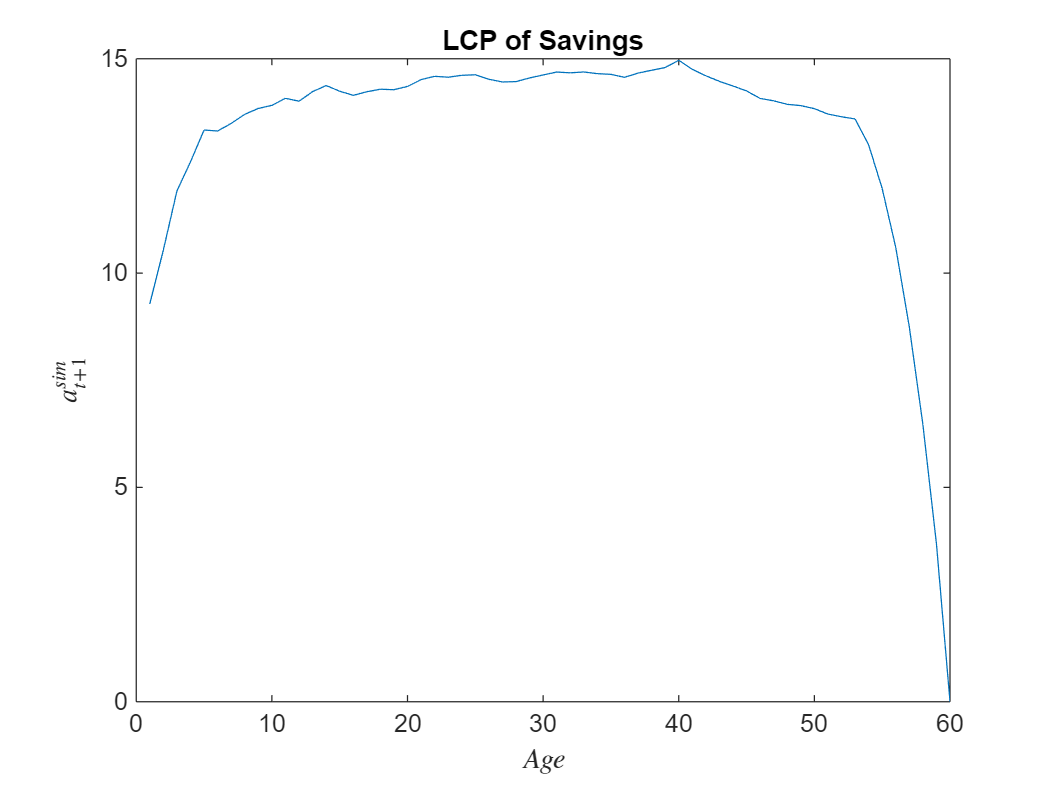

sim = q_simulate.lc(par, sol); % Simulate the model.
q_my_graph.plot_policy(par, sol, sim);% Plot the model functions and time series.